## `Questions`

`1.`` Describe the properties of the data (sub)set that you will classify: (i) How many points? (ii) What area does it cover? (iii) What observed features will you use? (iv) Visualize your final subset, including the useful observed features. (vi) Describe your at least four different object classes; For each point determine neighborhoods of k1, k2, ... points (using e.g. an efficient data structure), and use these k1, k2, ... points to estimate several feature values.`

`2.`` Describe $``\gt``$ 20 different geometric attributes, obtained using at least 2 different neighborhood sizes, to characterize your points. What are the dimensions of the data covariance matrix you use to compute the geometric features? Give one example on how you determine the PCA eigenvalues of one k-neighborhood. Indicate for each feature how it could help to distinguish your classes, given also the neighborhood sizes you consider.`

`3.`` Compute all geometric features for all points in your subset using Python. Visualize selected results, e.g. by combining features in a false color visualization and/or using histograms. Which features are best at discriminating your classes? Why?`

`4.`` Describe and visualize your training data. Is your training data balanced? Make sure that a zone of your point cloud data is really ’unseen’, that is that no training data is taken from that zone, so you can inspect if Random Forest also works there. `

`5.`` Feed your training data to Random Forest using at least 10 of your best geometric and observed features. What settings did you use? `

`6.`` Classify your point cloud data and visualize and discuss your result. What went well? Give also examples where the classifier mixed up classes. What are possible explanations for these confusions? How are the classification results on the unseen zone?`

% defining area of interest
xcenter = 89400;
bbbox_size = 500;
xmin = xcenter - 0.5*bbbox_size;
ycenter = 472868;
xmax = xcenter + 0.5*bbbox_size;
ymin = ycenter - 0.5*bbbox_size;
ymax = ycenter + 0.5*bbbox_size;
path = fullfile("assignment4/CloudComPy39/AHN4/AHN4_Noordwijk.laz");
lasReader = lasFileReader(path);
[pc,patt] = readPointCloud(lasReader,"Attributes","ScanAngle","ROI",[xmin xmax ymin ymax -inf inf])

pc =   pointCloud with properties:

     Location: [11541246×3 single]
        Count: 11541246
      XLimits: [89150 89650]
      YLimits: [472618 473118]
      ZLimits: [0.0920 73.5470]
        Color: [11541246×3 uint8]
       Normal: []
    Intensity: [11541246×1 uint8]


patt = struct with fields:
    ScanAngle: [11541246×1 single]


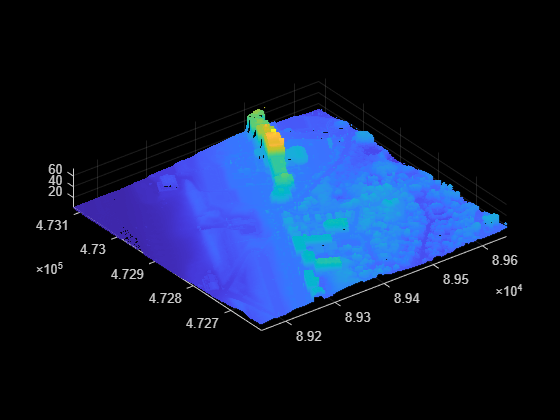

figure
pcshow(pc.Location)

mlxloc = strcat(pwd,'\assignment4\matlab.mlx');
fileout = strcat(pwd,'\assignment4\matlab_pointcloud.html');
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);